# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 800; % # sample points
A = 21; % Magnitude/Amplitude of droplet

xMax = 80; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
var = [A;N;k;y0]; 

% Set time span
tfinal = 10^5; % final time >> 1
tSpan = [1e-6 tfinal]; 

% Fixxed Disjoinning pressure
% c0(1) = 0.0002;  
% c0(2) = 0.0046;
c0(1) = 0.001;  
c0(2) = 0.0196;

% Condition
conds0 = [c0(1),c0(2)];

% Creating test matrix to soolve ODE
D1 = full(gallery('tridiag',N,-1,0,1));
D1(N,1)=1;D1(1,N)=-1;
D1 = D1/(2*dx);
D1 = sparse(D1); % D1
D2 = full(gallery('tridiag',N,1,-2,1));
D2(N,1)=1;D2(1,N)=1;
D2 = D2/dx^2;
D2 = sparse(D2); % D2

**Target Shape **`h_target`

h_target = 0.1*ones(size(X));
h_target(2.5 - X.^2/12>0.1) = 2.5 - X(2.5 - X.^2/12>0.1).^2/12;
% Target shape is a parabola, not achievable

## **2) **

**Initial droplet centered around **`x0`

h0 = hFinal(conds0,X,var,D1,D2,tSpan);
H0 = deval(h0,tfinal); 

## **3)**

**Solution**

% Vertical/Function tolerance: 1e-1
% Horizontal tolerance: 1e-1
options = optimset('Display','iter','TolFun',1e-1,'TolX',1e-1,'MaxFunEvals',2*60,'MaxIter',2*50);

% Generate an object/function to be optimise
myObjective_Possition = @(conds) costEvaluation(conds,X,var,D1,D2,tSpan,tfinal,h_target);
% in this case we have a cost function

figure;

plot(X,h_target,'k:','linewidth',2);
title('2-D profile of droplet')
xlabel('x')
ylabel('u(x)')
hold on
plot(X,H0,'*r');
ylim([0 5]);
grid on

% Solution of best center point: x_sol
[conds_Sol,fval,exitflag,output,history] = myproblem(myObjective_Possition,conds0);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          58.7335         
     1            3          51.0643         initial simplex
     2            5          25.1066         expand
     3            7          10.7164         expand
     4            9          10.7164         contract outside
     5           11          10.5879         contract inside
     6           13          10.3791         contract inside
     7           15          10.3627         reflect
     8           17          9.51307         reflect
     9           18          9.51307         reflect
    10           20          7.94792         reflect
    11           22          7.94792         contract inside
    12           23          7.94792         reflect
    13           25          7.60108         reflect
    14           27          7.60108         contract inside
    15           31          7.60108         shrink
    16           33          7.60108         contract ou


% resulting portfolio
h_Sol = hFinal(conds_Sol,X,var,D1,D2,tSpan);

% resulting final profile (at t = tfinal)
H_Sol = deval(h_Sol,tfinal);

plot(X,H_Sol,'*g')
legend('Exp Data','Initial Param','Best Param');
hold off

history

history =     0.0010    0.0196
    0.0011    0.0196
    0.0011    0.0176
    0.0012    0.0167
    0.0012    0.0167
    0.0011    0.0170
    0.0012    0.0164
    0.0011    0.0167
    0.0011    0.0161
    0.0011    0.0161


figure;
grid on

n = size(history);
n = n(1);
m = size(H_Sol);
m = m(1);
p = ones(n,m);
for i = 1:n
    p(i,:)=deval(hFinal(history(i,:),X,var,D1,D2,tSpan),tfinal);
end
plot(X,p)
grid on

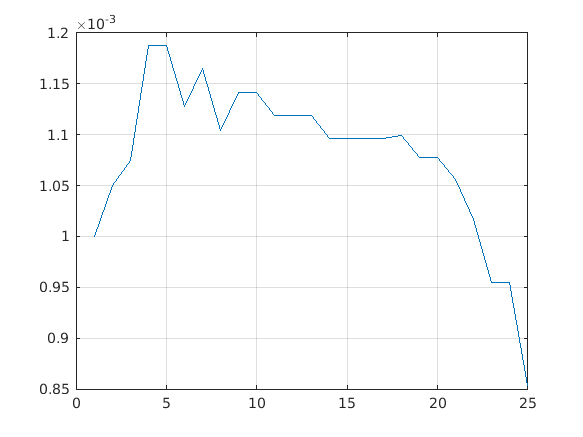

figure;
% subplot(4,1,1);
plot(history(:,1));
xlim([0 25]);
grid on

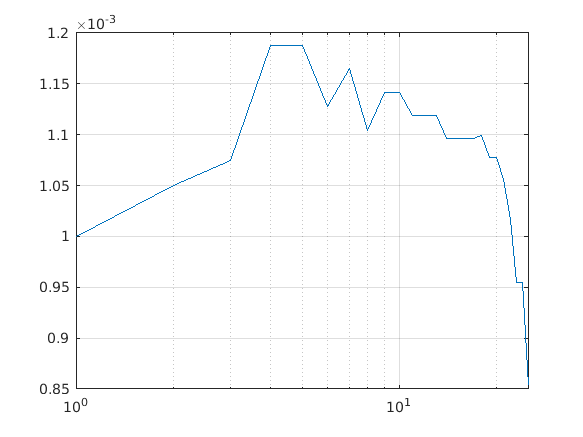

% subplot(4,1,2);
semilogx(history(:,1));
xlim([0 25]);
grid on

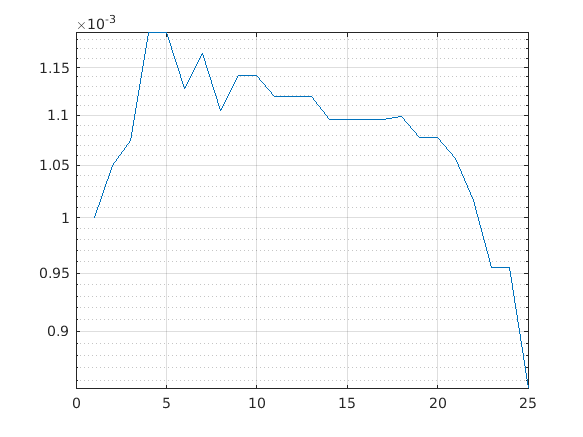

% subplot(4,1,3);
semilogy(history(:,1));
xlim([0 25]);
grid on

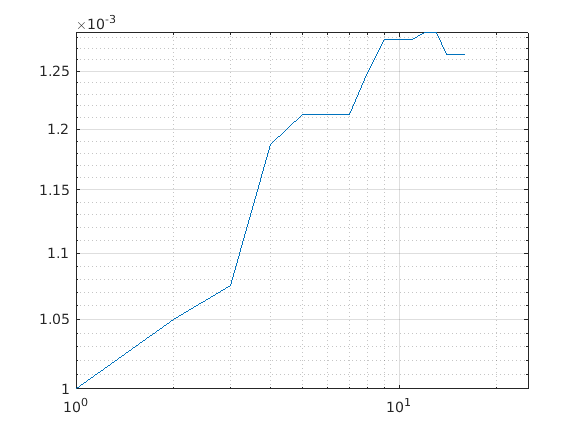

% subplot(4,1,4);
loglog(history(:,1));
xlim([0 25]);
grid on

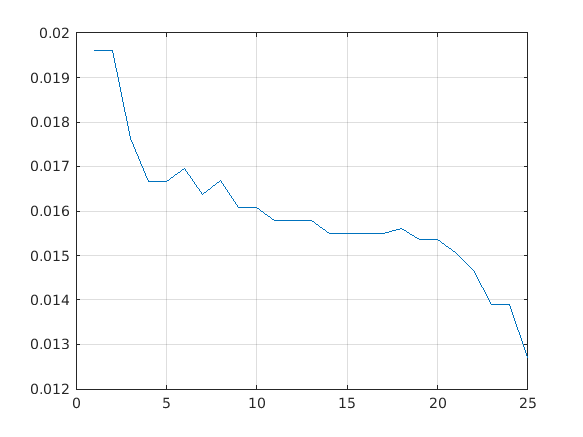



figure;
% subplot(4,1,1);
plot(history(:,2));
xlim([0 25]);
grid on

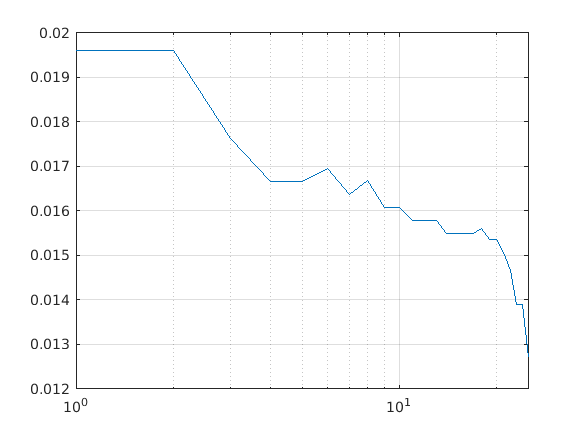

% subplot(4,1,2);
semilogx(history(:,2));
xlim([0 25]);
grid on

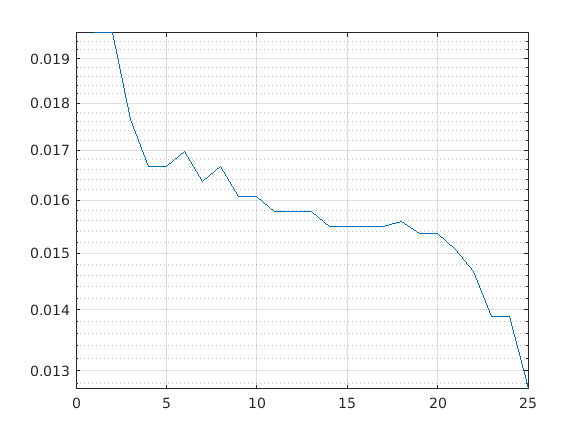

% subplot(4,1,3);
semilogy(history(:,2));
xlim([0 25]);
grid on

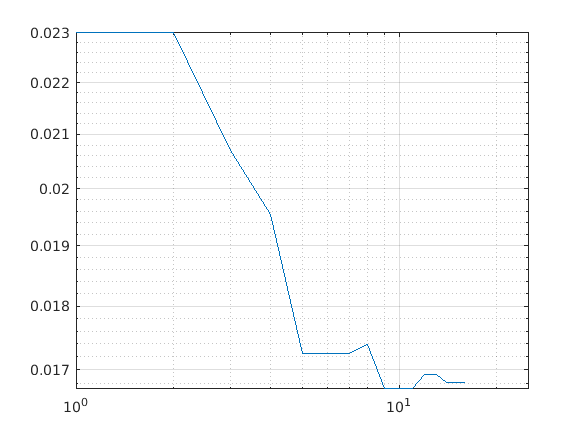

% subplot(4,1,4);
loglog(history(:,2));
xlim([0 25]);
grid on



% figure;
% % subplot(4,1,1);
% plot(history(:,3));
% xlim([0 25]);
% grid on
% % subplot(4,1,2);
% semilogx(history(:,3));
% xlim([0 25]);
% grid on
% % subplot(4,1,3);
% semilogy(history(:,3));
% xlim([0 25]);
% grid on
% % subplot(4,1,4);
% loglog(history(:,3));
% xlim([0 25]);
% grid on
